# Aritmética de Matlab

a = 4/3

a =        1.3333


b = a - 1

b =       0.33333


c = b + b + b

c =             1


e = 1 - c

e =    2.2204e-16


Sistema lineal

A = [10 1; 3 0.3]

A =            10            1
            3          0.3


b = [11 3.3]'

b =            11
          3.3


x = A\b 

x =    Inf
  -Inf


det(A)

ans =      0


Error d'arrodoniment

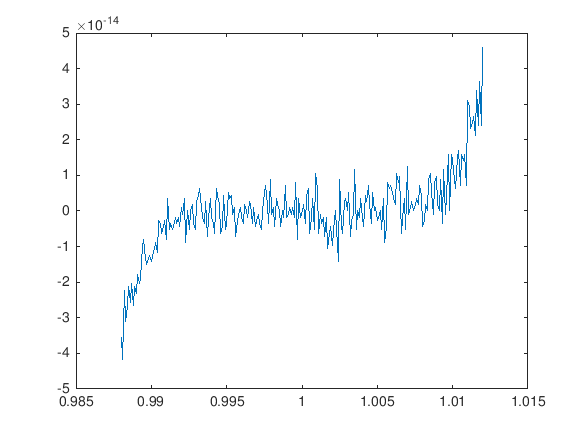

x = 0.988:.0001:1.012;
y = x .^ 7 - 7 * x .^ 6 + 21 * x .^ 5 - 35 * x .^ 4 + 35 * x .^ 3 - 21 * x .^ 2 + 7 * x - 1 ;
plot( x , y )

Algorísme


$$$x_k =\frac{1}{2}\left(x_{k-1}+\frac{2}{x_{k-1}\)$$


format shortG %longG
x=3;
R=[0,x,e]

R =             0            3   2.2204e-16


for k=1:6;
    x=(x+2/x)/2;
    e=abs(x-sqrt(2));
    R=[R; k,x,e];
end
disp('matriu de resultats')

matriu de resultats


R

R =             0            3   2.2204e-16
            1       1.8333      0.41912
            2       1.4621     0.047908
            3        1.415   0.00078487
            4       1.4142   2.1767e-07
            5       1.4142   1.6653e-14
            6       1.4142   2.2204e-16


Taula

T = array2table(R,...
    'VariableNames',{'k','x','error_absolut'})

T = 7×3 table
    k      x       error_absolut
    _    ______    _____________

    0         3     2.2204e-16  
    1    1.8333        0.41912  
    2    1.4621       0.047908  
    3     1.415     0.00078487  
    4    1.4142     2.1767e-07  
    5    1.4142     1.6653e-14  
    6    1.4142     2.2204e-16  


Seleccionar elements per veure

T(1:3:end,:)

ans = 3×3 table
    k      x       error_absolut
    _    ______    _____________

    0         3     2.2204e-16  
    3     1.415     0.00078487  
    6    1.4142     2.2204e-16  


Escriure resultats en fitxer

x = 0:.1:1;
A = [x; exp(x)];

fileID = fopen('exp.txt','w');
fprintf(fileID,'%6s %12s\n','x','exp(x)');
fprintf(fileID,'%6.2f %12.8f\n',A);
fclose(fileID);

a=0;
b=sin(pi);
a==b

ans = logical
   0


abs(a-b)<1e-14

ans = logical
   1
